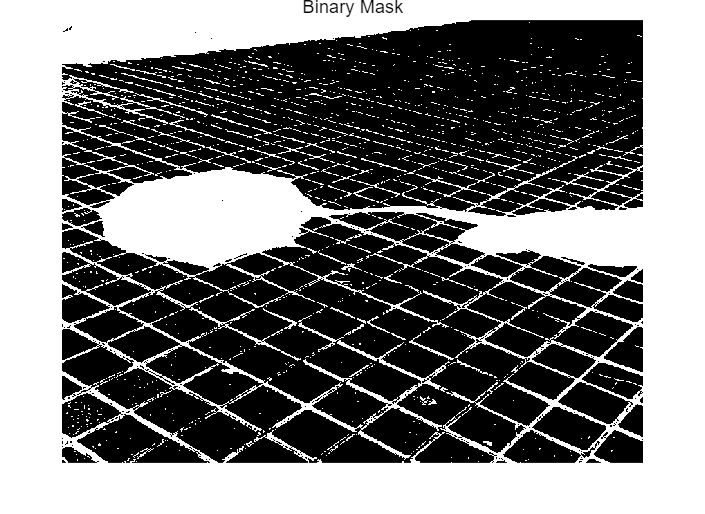

% 读取图像
or_img = imread('../resources/_MG_5844.jpg');

% 将图像从 RGB 转换为 YCbCr
y_cb_cr_img = rgb2ycbcr(or_img);

% 创建一个二值掩码
binary_mask = y_cb_cr_img;

% 获取 Y 通道的均值和标准差
y_channel = y_cb_cr_img(:, :, 1);  % 提取 Y 通道
y_mean = mean(y_channel(:));
y_std = std(double(y_channel(:)));

% 初始化二值掩码
for i = 1:size(y_cb_cr_img, 1)
    for j = 1:size(y_cb_cr_img, 2)
        if y_cb_cr_img(i, j, 1) < y_mean - (y_std / 3)
            % 将阴影区域标记为白色
            binary_mask(i, j, :) = [255, 255, 255];
        else
            % 非阴影区域标记为黑色
            binary_mask(i, j, :) = [0, 0, 0];
        end
    end
end

% 使用形态学操作
se = strel('square', 6);  % 定义一个 3x3 的结构元素
open = imopen(binary_mask,se);
result = bitand(open,binary_mask);

% 计算亮区和阴影区域的像素强度
spi_la = 0;  % 亮区的像素强度总和
spi_s = 0;   % 阴影区的像素强度总和
n_la = 0;    % 亮区的像素数
n_s = 0;     % 阴影区的像素数

for i = 1:size(y_cb_cr_img, 1)
    for j = 1:size(y_cb_cr_img, 2)
        if all(erosion(i, j, :) == [0, 0, 0])  % 如果是亮区（非阴影）
            spi_la = spi_la + double(y_cb_cr_img(i, j, 1));  % 累加亮区的 Y 值
            n_la = n_la + 1;
        else  % 如果是阴影区
            spi_s = spi_s + double(y_cb_cr_img(i, j, 1));  % 累加阴影区的 Y 值
            n_s = n_s + 1;
        end
    end
end

% 计算亮区和阴影区的平均亮度
average_ld = spi_la / n_la;
average_le = spi_s / n_s;

% 计算亮区与阴影区亮度的差异和比率
i_diff = average_ld - average_le;
ratio_as_al = average_ld / average_le;

% 调整阴影区域的亮度和颜色
for i = 1:size(y_cb_cr_img, 1)
    for j = 1:size(y_cb_cr_img, 2)
        if all(erosion(i, j, :) == [255, 255, 255])  % 如果是阴影区域
            y_cb_cr_img(i, j, 1) = y_cb_cr_img(i, j, 1) + i_diff;  % 增加亮度
            y_cb_cr_img(i, j, 2) = y_cb_cr_img(i, j, 2) + ratio_as_al;  % 调整 Cr 通道
            y_cb_cr_img(i, j, 3) = y_cb_cr_img(i, j, 3) + ratio_as_al;  % 调整 Cb 通道
        end
    end
end

% 将 YCbCr 图像转换回 RGB
final_image = ycbcr2rgb(uint8(y_cb_cr_img));

% 显示原图和处理后的图像
figure;
imshow(binary_mask);
title('Binary Mask');

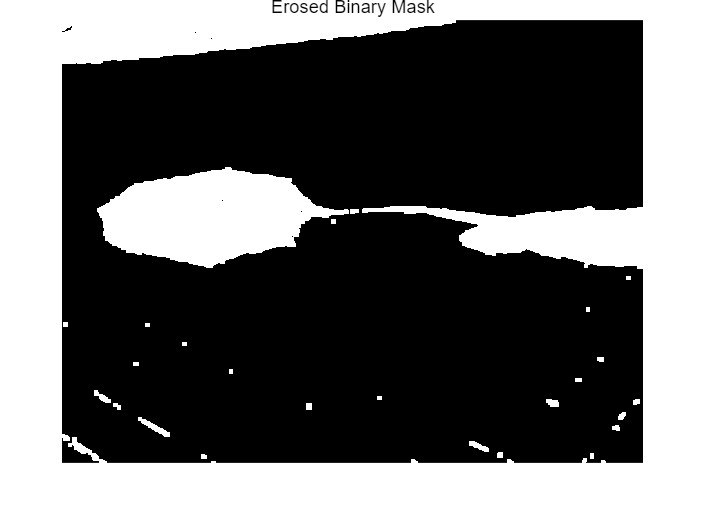

figure;
imshow(open,[]);
title("Erosed Binary Mask");

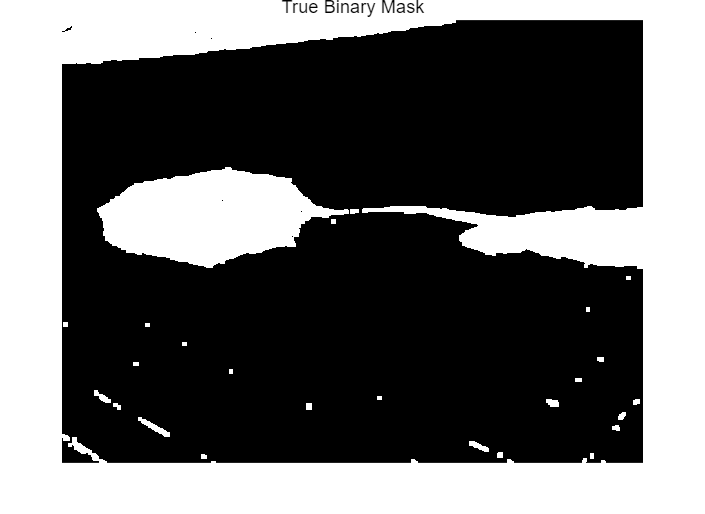

figure;
imshow(result,[]);
title("True Binary Mask");

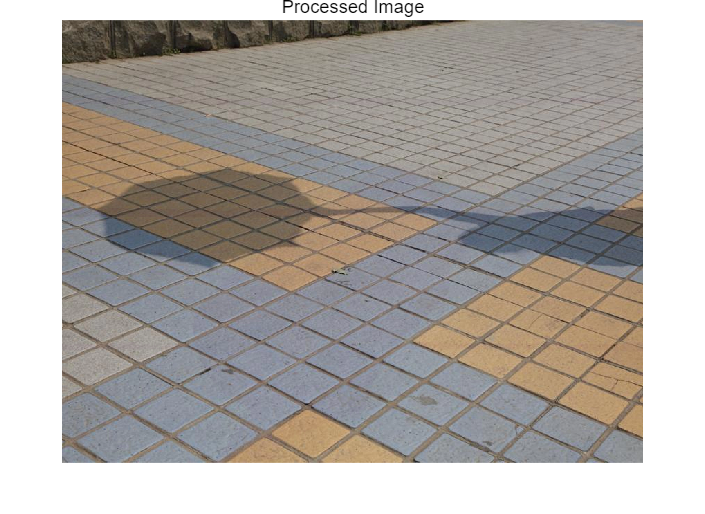

figure;
imshow(final_image);
title('Processed Image');